# Defining region of interest (ROI) and cropping data for local analysis

**Creation of ROI, extraction of data set, 1D concentration profile along ROI axis**

In order to analyze a specific section of the data set, the user can create a region of interest. To start with the creation of a ROI, a 3D reconstruction of the APT tip and a ranged pos file are required. The live scripts **FirstSteps **and **3D visualisation of APT data** will guide the user through these required steps.

**Side note:** If a former 3D reconstruction was already saved, the user can load the saved MATLAB figure and create a ROI. However, before starting with the first steps of creating the ROI, the user has to open the figure and enter *ax = gca; *in the command line. After this, the user can proceed with the following steps.

## Creating a ROI

In this toolbox four different shaped ROIs are implemented. The user can either create a plane, a box, a cylinder, or a sphere of defined dimensions.

### Creating a ROI plane

For the creation of a plane, the user has to specifiy the length and width of the plane and the spacing of the subdivisions (in both dimensions). The inputs for the center of the plane (*location*) and the axis, in which the ROI is orientated, are optional.

dimensions =[70 70]; % length (x direction) and width (y direction) of the plane
spacing = [35 35]; % spacing in x and y direction
location = [0 0 40]; % x, y, and z coordinates of the plane's center, default is [0 0 0]
roi_plane = roiCreatePlane(dimensions,spacing,location,ax);
 

### Creating a ROI box

The box shaped ROI is created by the *roiCreateBox* function. The dimensions are defined by values corresponding to length, width, and height in x-, y-, and z-direction, respectively. The origin is determined by x, y, and z coordinates. The user can also set the axis, in which the ROI is orientated.

All these inputs are optional. If no input is used, the default dimensions correspond to a cube with a side length of 10, an origin in (0,0,0) and the current axis of the figure.  

dimensions = [10 10 10]; % length, width, and height (x,y,z) of the ROI in nm
location = [0 0 40]; % origin coordinates of the ROI
roi_box = roiCreateBox(dimensions,location,ax);

Error using patch
Value must be a handle.

Error in roiCreateBox (line 66)
bh = patch(ax,'Vertices',vertices,'Faces',faces);

### Creating a ROI cylinder

To create a cylinder shaped ROI the *roiCreateCylinder* function is used. All inputs are optional. The default values are a radius of 5 nm, a height of 10 nm, a origin of (0,0,0) and a number of segments, which depict the cylinder, of 32. Also, the user can set the axis, in which the ROI is orientated.

This function needs the wanted radius, height, location, and number of segments of the cylinder.

radius = 5; % radius of the cylinder in nm
height = 10; % height of the cylinder in nm
location = [0 0 40]; % origin coordinates of the ROI
numSegments = 32; % number of segments of the cylinder
roi_cylinder = roiCreateCylinder(radius,height,location,numSegments,ax);
 

### Creating a ROI sphere

The user can create a sphere shaped ROI with the roiC*reateSphere* function. 

radius = 15; % radius of the sphere
subDivisions = 15; % number of subdivisions of the sphere
location = [0 0 40]; % origin coordinates of the ROI
roi_sphere = roiCreateSphere(radius,subDivisions,location,ax);
 

### Cropping of data using the *cropping* app

With the *cropping* app, the user can create a box shaped section of the APT tip with defined dimensions. The app's user interface can be seen in the figure below.

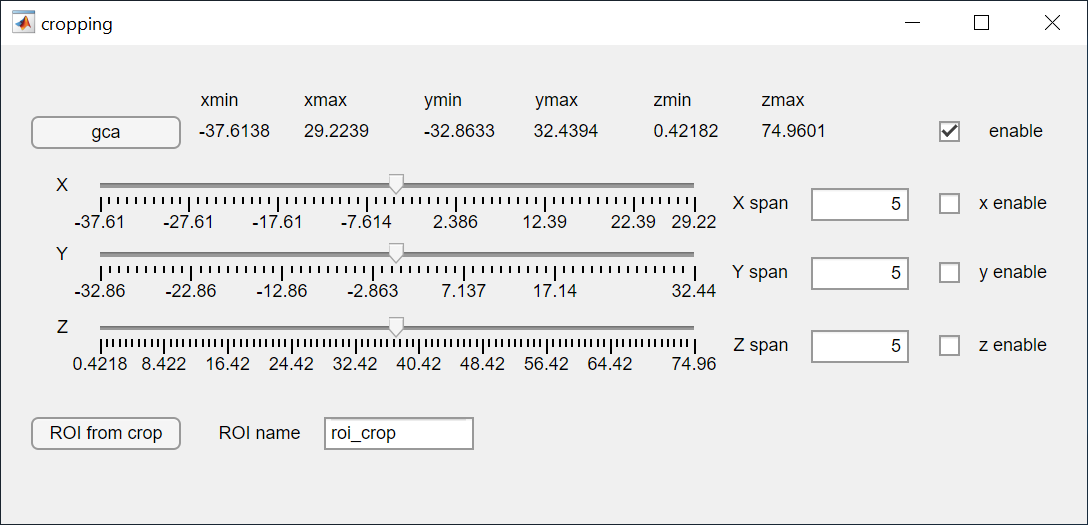

Initially, the axes of the reconstruction must be parsed by clicking the *gca* button within the app. It is essential, that the wanted figure is the current figure. Subsequently, the user can define the cropping size in x, y, and z direction by inserting a number (in nm) in the edit field next to e.g. *X span* and then ticking off the corresponding square next to e.g. *x enable*. Each of the axes can be selected independently. However, all changes only become active when the *enable* box in the top right corner is activated.

The main difference of this app compared to the function *roiCreateBox* is, that during the creation of the box, the viewed section of the APT tip in the figure gets simultaneously cropped to the specified dimensions. By sliding the arrow of the corresponding enabled dimension, the user can slide the ROI in the wanted direction. Therefore, this app is also ideal for visual investigations of the elemental distribution along the x, y, or z axis by sliding.

After adjusting both the dimensions and the position of the wanted section, a ROI can be cropped by clicking the *ROI from crop* button. Beforehand, a *ROI name* must be given. The so created ROI gets saved as a patch in the workspace. Furthermore, the ROI box in inserted in the current figure. By clicking on the *enable* box in the top right corner, the entire data set is shown again.

SIDE NOTE: The arrow position marks the middle of the *span*, therefore the displayed values on top (*xmin*, *xmax*, *ymin*, *ymax*, *zmin*, and *zmax*) differ about half of the span value.

## Manipulating the ROI

After the user created the ROI in the wanted shape it can be moved, turned and changed in size with the *roiManipulate* app (see figure). 

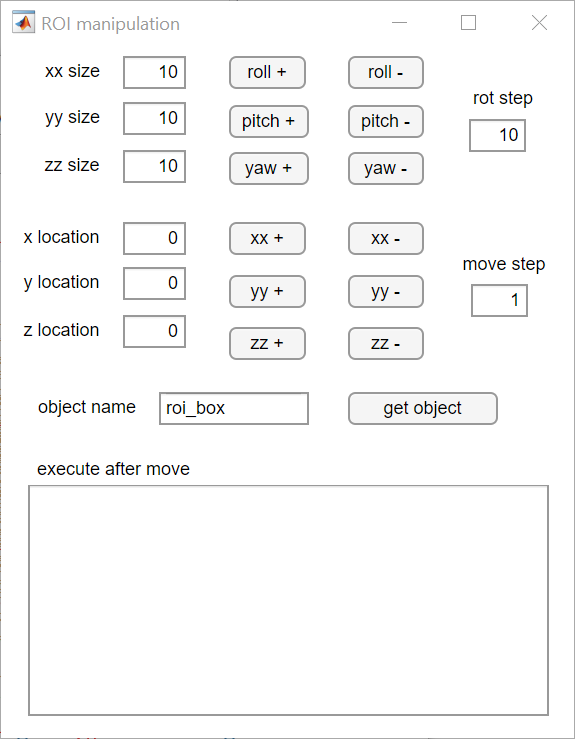

Before the user can change position and size of the ROI, the user has to insert the object name and hit the *get object* button. Then the user can easily change the size of the ROI by entering it in the respective field. The location of the object can also be changed directly or via the buttons provided. By changing the value in the *rot step* or *move step *fields, the user can change the precision of the movement.

roiManipulate; % in case of wanted changes in size, location, or orientation of the ROI
 

Additionally, the user can put in commands in the field *execute after move*, which shall be executed after each change in position or size. This can be rather useful for the comparison of various regions concerning the corresponding 1D concentration profile, the visualisation of the section encapsulated by the ROI, and others.

## **Plotting of a 1D concentration profile of a ROI box or cylinder**

While the plotting of a 1D concentration profile of an entire data set is already explained in the live script **1DConcentrationProfile**, it is necessary for the plotting of a ROI shape to execute a few commands beforehand.

NOTE: A 1D concentration profile may only be advisable for a ROI in the shape of a box or a cylinder.

### Cropping of the data within the created ROI

With the function *posInConvexHull* it is possible to crop the data points encapsulated by the ROI (as long as the ROI's confining surfaces are convex) and create a separated *pos_roi* file for further data analysis. Therefore, only three dimensional ROIs can be used. 

roi = roi_box; % selection of the ROI shape
pos_roi = pos(posInConvexHull(pos,roi.Vertices),:); % extraction of data only from ions within ROI
 

### Transformation of the data to ROI's coordinate system

A transformation of the data to ROI's coordinate system is only necessary, if the ROI was moved in a way that the axis, which specifies the direction of plotting, has changed with respect to the corresponding axis of the initial data set.

ROIobject = roi; % ROI shape, which was specified in the previous step
points = pos_roi; % points wihin the ROI shape
pos_roi_trans = coordSystemTransform(ROIobject,points); % transformation of the coordinate system
 

The next sections are identical with the first steps of the live script **1DConcentrationProfile**. The only changes are the exchange of *pos* with *pos_roi_trans*.

### Creation of grid vectors

The function *binVectorsFromDistance* creates a set of grid vectors to be used in nD binning (here for one dimension). First, the distance variable needs to be specified, in which the binning will be performed. If no particular ROI is wanted, the typical distance is represented by the z axis of the pos variable.

dist = pos_roi_trans.y; % determine the distance variable to be binned
 

There are **two modes** possible. The user has to choose the wanted case and comment the unwanted case in this live script (either by pushing the button in the task bar or pressing the keys *Ctrl + R*) in order to execute the live script properly since the input variables *bin* and *mode* are practically 'connected' (for the mode *'distance'*  values between 1 and around 20 make sense, whereas the mode *'count'* needs much higher values).

**Case #1:** *'distance'* is used as *mode*, which resembles the distance in nm from bin edge to bin edge

bin = 0.1; % bin width in nm
mode = 'distance';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

**Case #2:** *'count'* is used as *mode*, which resembles the number of counts, which are present between two consecutive bin edges

bin = 5000; % number of counts within each bin
mode = 'count';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

### Voxelisation of the data set

In the next step, the voxelisation will be performed based on the bin edges. This means in 1D, that the reconstructed APT tip is separated into slices of the size determined in the previous step. 

Each slice exhibits either a specified thickness in nm (for mode *'distance'*) or consists of a certain number of counts (for mode *'count'*). As a side note, be aware that the final slice most likely is thinner or contains less atoms compared to the other slices. This is only logical and relates to the way the slices are created.

vox = posNdBin(pos_roi_trans,dist,binEdges); % creates a cell array of various pos subsets, representing the voxelisation of the pos variable
 

### Creation of an anonymous function

In the next step, a so-called 'anonymous function' will be defined. This means that a function handle will be created, here it is called *concentrationKernel*. By doing so, the subsequent step can be executed more easily.

As input, the detector efficiency is needed. For example, in case of the LEAP 4000X HR, this value is 0.37 or 37 %, respectively.

The inputs *excludeListConc* and *volumeName* are optional:

detEff = 37; % detector efficiency, input as decimal or percentage figure possible
excludeListConc = {'unranged' }; % list of ions that shall not be considered for the concentration calculation, unranged atoms appear as 'unranged', optional
volumeName = '4622 AP49 RTLO Fe14 C'; % name of the volumes, parsed as character array, optional
concentrationKernel = @(pos_roi_transXYZ) posCalculateConcentrationSimple(pos_roi_transXYZ,detEff,excludeListConc,volumeName);
 

### Plotting of a 1D concentration profile

In order to plot a 1D concentration profile, it is necessary to execute following function so that the calculated concentration values correspond to a distance value.

conc1D = binApplyConcentrationKernel(vox,binCenters,concentrationKernel,{'nm'});

To plot the concentration over the distance, the function *concentrationProfilePlot* is needed. The user can specify an exclude list (now *excludeListPlot*) to exclude certain species from plotting.

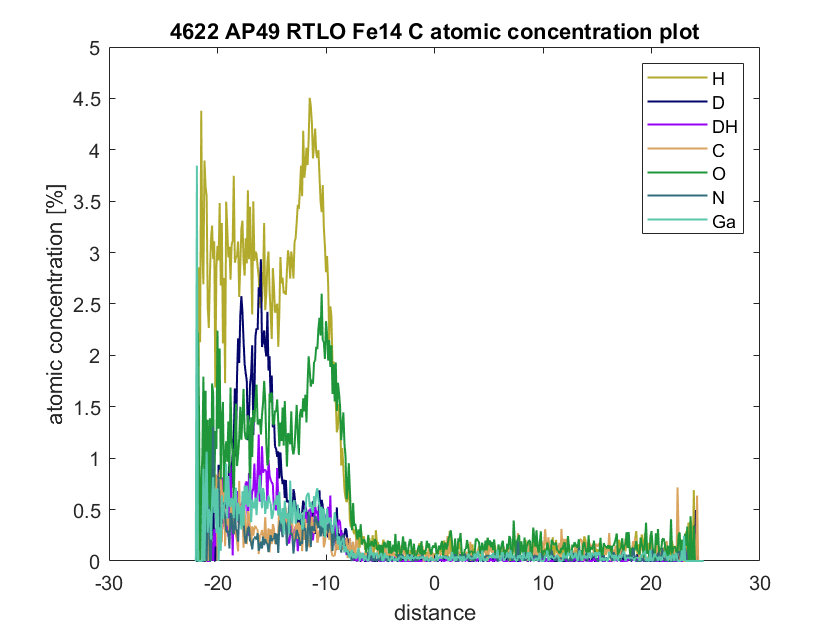

excludeListPlot = {'unranged', 'Fe'};  % list of ions that shall not be displayed in the plot, optional
[p, ax, f] = concentrationProfilePlot(conc1D([conc1D.format=='concentration'],:),excludeListPlot,colorScheme); % plots the wanted species over the distance